Let $f(x)=e^{-1.3x}$. We apply finite difference formulas of first, second, and fourth order to estimate $f'(0)=-1.3$.

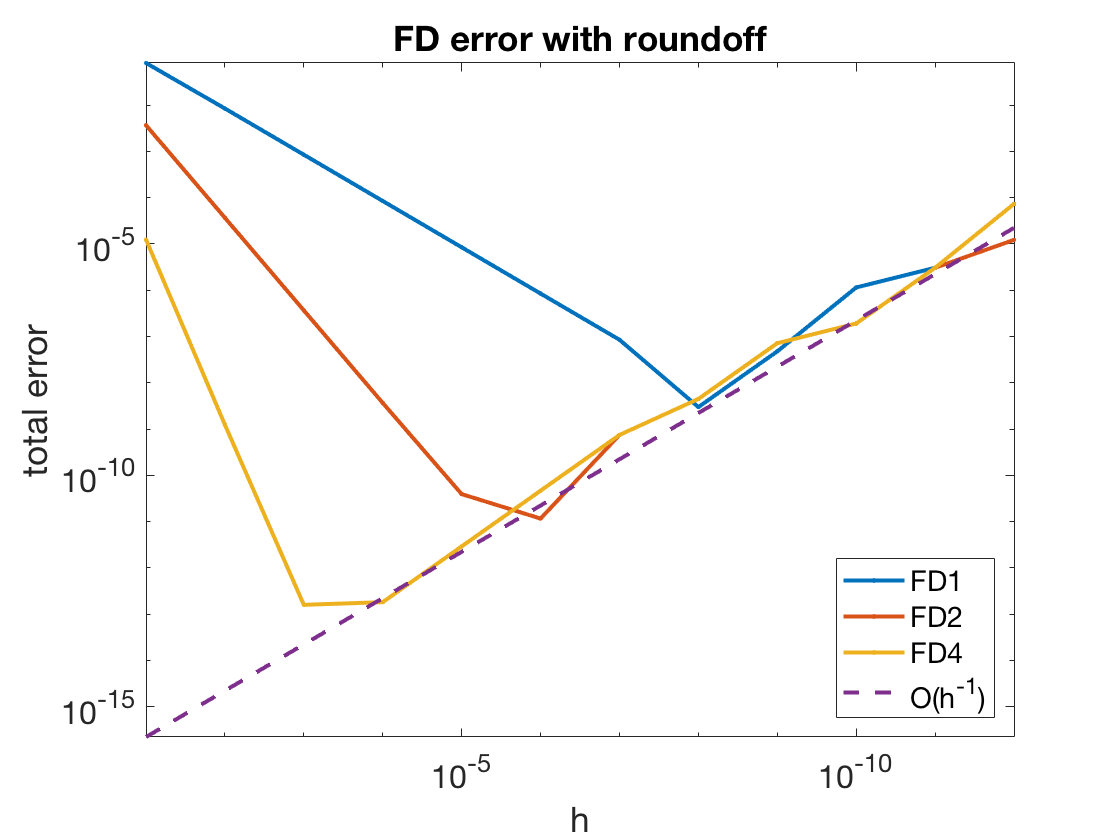

h = 10.^(-1:-1:-12)';
f = @(x) exp(-1.3*x);
for j = 1:length(h) 
    nodes = h(j)*(-2:2)';
    vals = f(nodes)/h(j);
    fd1(j) = [   0    0 -1    1     0] * vals;
    fd2(j) = [   0 -1/2  0  1/2     0] * vals;
    fd4(j) = [1/12 -2/3  0  2/3 -1/12] * vals;
end
loglog(h,abs(fd1+1.3),'.-'), hold on
loglog(h,abs(fd2+1.3),'.-')
loglog(h,abs(fd4+1.3),'.-')
loglog(h,0.1*eps./h,'--')
set(gca,'xdir','reverse')
legend('FD1','FD2','FD4','O(h^{-1})','location','southeast')  % ignore this line
xlabel('h'), ylabel('total error')     % ignore this line
title('FD error with roundoff'), axis tight    % ignore this line

Again the graph is made so that $h$ decreases from left to right. The errors are dominated at first by truncation error, which decreases most rapidly for the 4th order formula. However, increasing roundoff error eventually equals and then dominates the truncation error as $h$ continues to decrease. As the order of accuracy increases, the crossover point moves to the left (greater efficiency) and down (greater accuracy). 